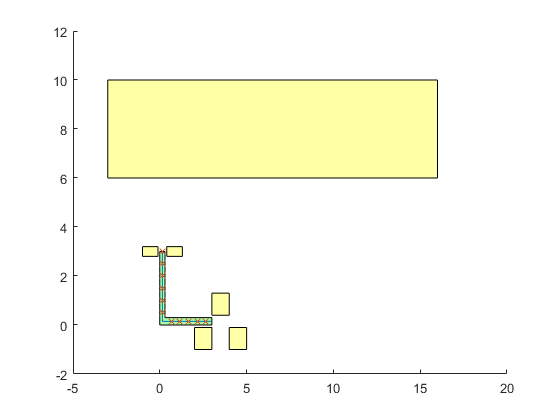

clear

% RRT*:
KD_RRT_Star_Time  = [];
KD_iter           = [];
IsDebug           = false;

% Printing:
sampled_start_pts = [];
[Printing_Poly, printing_path_checkpoints, printing_progress] = Printing(1);
Obstacles_Poly                                                = Environment();


% Possible starting points in the printing task:
branching_pts      = BranchingPoints(printing_path_checkpoints, printing_progress, Printing_Poly, Obstacles_Poly);
branched_start_pts = BranchedStartingPoints(10, branching_pts, printing_progress, printing_path_checkpoints, Printing_Poly, Obstacles_Poly);

for ith_start = 1:1000 % number of starting points to grow RRT*
    [rand_start_pt, current_IRM] = Fake_sampleIRM(printing_path_checkpoints(1,:), printing_progress(1), IsDebug);
    sampled_start_pts            = [sampled_start_pts; rand_start_pt];
end

if IsDebug
    scatter(sampled_start_pts(:,1), sampled_start_pts(:,2),'filled', 'MarkerFaceColor', '#77AC30')
    current_IRM_plot = fill(current_IRM(1,:), current_IRM(2,:), 'b', 'FaceAlpha', 0.2, 'EdgeColor',"none");
    delete(current_IRM_plot);
end

% start length(branched_start_pts{1}) instances
% search length(branching_pts) in parallel
% 
% if value of branching < 0.5 search forward, else if > 0.5 search
% backwards??

% for trial_idx = 1:length(branched_start_pts{1})
%     % parallel how???
% end

parfor idx = 1:length(sampled_start_pts(:,1))
    % Init:
    KDRRT                           = CLS_KDRRTStar;
    KDRRT.IsDEBUG                   = IsDebug;
    KDRRT.NN_method                 = 'KDTree_angle_diff_sq_norm';
    KDRRT.s_f                       = max(printing_progress);
    KDRRT.r_start                   = sampled_start_pts(idx,:);
    KDRRT.Printing_Poly             = Printing_Poly;
    KDRRT.Obstacles_Poly            = Obstacles_Poly;
    KDRRT.printing_path_checkpoints = printing_path_checkpoints;
    KDRRT.printing_progress         = printing_progress;
    
    tic;
    [path, ite] = KDRRT.RRT_Star
    time = toc;
    disp(['Trial ' + string(idx) + ' Found path in ' + string(ite) + ' iterations.'])
    KD_iter          = [KD_iter, ite];
    KD_RRT_Star_Time = [KD_RRT_Star_Time, time];
    hold off
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


Error using CLS_KDRRTStar/RRT_Star (line 126)
Number of fields in structure arrays being concatenated do not match. Concatenation of structure arrays requires that these arrays have the same set of fields.

hold off
scatter(KD_iter, KD_RRT_Star_Time)
xlabel('Number of iterations')
ylabel('RRT* runtime (sec)')